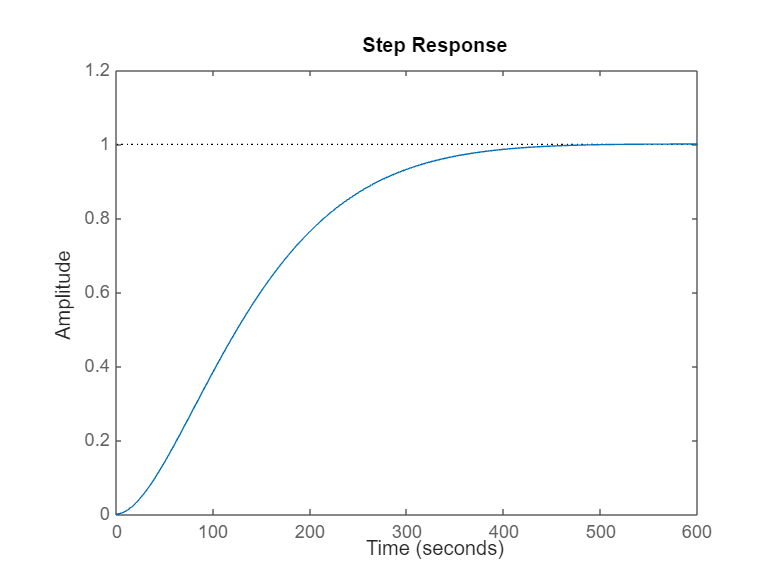

%%Reference tf
km  = 1.6211e-04;
bm  = 1;
am1 = 0.0232;
am2 = 1.6211e-04;
% km  = 0.21261;
% bm  = 1;
% am1 = 0.8;
% am2 = 0.2126;
% km  = 0.008504347681652;
% bm  = 1;
% am1 = 0.160000000000000;
% am2 = 0.008504347681652;
%%Transfer fun
Tfm=tf([km km*bm],[1 am1 am2]);
%%Step
step(Tfm)

stepinfo(Tfm)  

ans = struct with fields:
         RiseTime: 230.3747
    TransientTime: 377.6422
     SettlingTime: 377.6422
      SettlingMin: 0.9044
      SettlingMax: 1.0010
        Overshoot: 0.0965
       Undershoot: 0
             Peak: 1.0010
         PeakTime: 599.4661


[A,B,C,D]=tf2ss([km km*bm],[1 am1 am2])

A =    -0.0232   -0.0002
    1.0000         0


B =      1
     0


C = 1.0e-03 *

    0.1621    0.1621


D = 0

sys11 = ss(A,B,C,D)

sys11 =
 
  A = 
               x1          x2
   x1     -0.0232  -0.0001621
   x2           1           0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
              x1         x2
   y1  0.0001621  0.0001621
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


figure()
step(sys11)

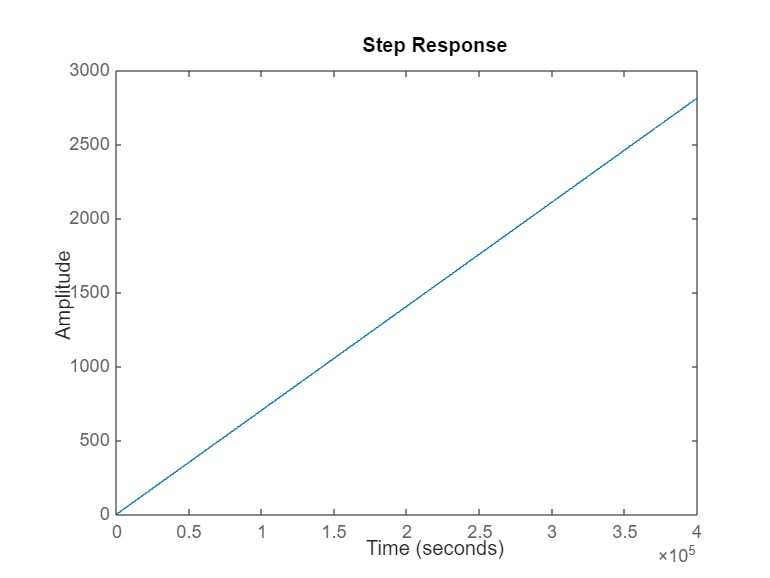

%%%Get the open loop
openLoop=feedback(Tfm,1,+1);
figure()
step(openLoop);


closeLoop = feedback(openLoop,1);

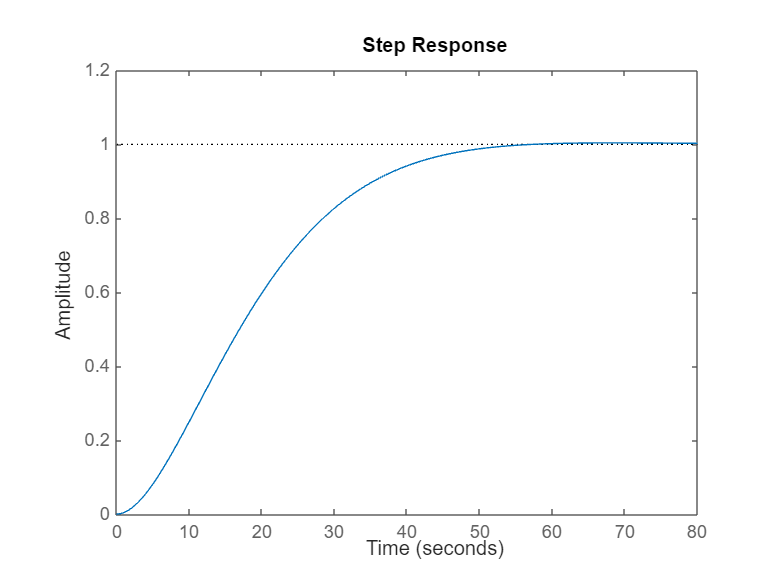

ans = struct with fields:
         RiseTime: 29.7204
    TransientTime: 47.2803
     SettlingTime: 47.2803
      SettlingMin: 0.9037
      SettlingMax: 1.0042
        Overshoot: 0.4175
       Undershoot: 0
             Peak: 1.0042
         PeakTime: 68.5019


% Definir el tiempo de asentamiento deseado
    Ts = 50; % segundos

    % Calcular los parámetros de la función de transferencia
    zeta = 0.8675; % coeficiente de amortiguamiento (ajustar según sea necesario)
    wn = 4 / (zeta * Ts); % frecuencia natural

    % Crear la función de transferencia
    sys = tf(wn^2, [1, 2*zeta*wn, wn^2]);
    step(sys); stepinfo(sys)

    ess_step = abs(1 - dcgain(sys))

ess_step = 0

PID Evaluation